clear all
close all
clc

L = [12, 7, 4];

TT_TOT = [];

Q_TOT = [];
QP_TOT = [];
QPP_TOT = [];

S_TOT = [];
SP_TOT = [];
SPP_TOT = [];

CC1_TOT= [];
CC2_TOT = [];
CC3_TOT = [];

EK_TOT = [];
EP_TOT = [];
E_TOT = [];

WW_TOT = [];
P_TOT = [];



load dati1.mat

T = tt(end);
TT_TOT = [TT_TOT tt];

Q_TOT = [Q_TOT Q];
QP_TOT = [QP_TOT Qp];
QPP_TOT = [QPP_TOT Qpp];

S_TOT = [S_TOT S];
SP_TOT = [SP_TOT Sp];
SPP_TOT = [SPP_TOT Spp];

CC1_TOT= [CC1_TOT CC1];
CC2_TOT = [CC2_TOT CC2];
CC3_TOT = [CC3_TOT CC3];

EK_TOT = [EK_TOT EK_tot];
EP_TOT = [EP_TOT EP_tot];
E_TOT = [E_TOT E_tot];

WW_TOT = [WW_TOT WW_tot];
P_TOT = [P_TOT P_tot];



load dati2.mat

tt = tt+T;
T = tt(end);
TT_TOT = [TT_TOT tt];

Q_TOT = [Q_TOT Q];
QP_TOT = [QP_TOT Qp];
QPP_TOT = [QPP_TOT Qpp];

S_TOT = [S_TOT S1];
SP_TOT = [SP_TOT Sp1];
SPP_TOT = [SPP_TOT Spp1];

CC1_TOT= [CC1_TOT CC1];
CC2_TOT = [CC2_TOT CC2];
CC3_TOT = [CC3_TOT CC3];

EK_TOT = [EK_TOT EK_tot];
EP_TOT = [EP_TOT EP_tot];
E_TOT = [E_TOT E_tot];

WW_TOT = [WW_TOT WW_tot];
P_TOT = [P_TOT P_tot];


load dati3.mat
tt = tt+T;
T = tt(end);
TT_TOT = [TT_TOT tt];

Q_TOT = [Q_TOT Q];
QP_TOT = [QP_TOT Qp];
QPP_TOT = [QPP_TOT Qpp];

S_TOT = [S_TOT S];
SP_TOT = [SP_TOT Sp];
SPP_TOT = [SPP_TOT Spp];

CC1_TOT= [CC1_TOT CC1];
CC2_TOT = [CC2_TOT CC2];
CC3_TOT = [CC3_TOT CC3];

EK_TOT = [EK_TOT EK_tot];
EP_TOT = [EP_TOT EP_tot];
E_TOT = [E_TOT E_tot];

WW_TOT = [WW_TOT WW_tot];
P_TOT = [P_TOT P_tot];



Plot tutti i grafici

** 2.1 PLOT**:

- Plot configurations:

%% plot configurations
n = 1500;
% Dati da cinematica diretta:
%Plot_Trajectory_AAA(Q(:,1),Q(:,end),L,S_TOT(1,:),S_TOT(2,:),S_TOT(3,:),n,"Mista",T);

% Dati da cinematica inversa:
%Plot_Trajectory_AAA(Q_inv(:,1),Q_inv(:,end),L,x,y,z,n,"Lineare");

- Plot graph of data x,y,z position speed and acceleration direct kinematics:

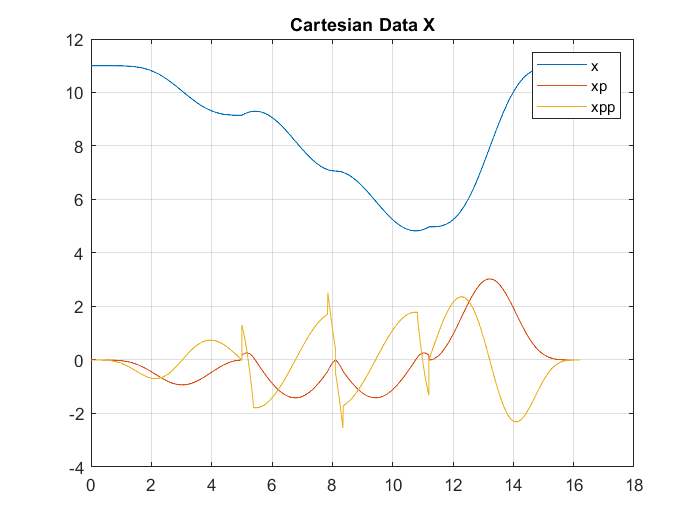

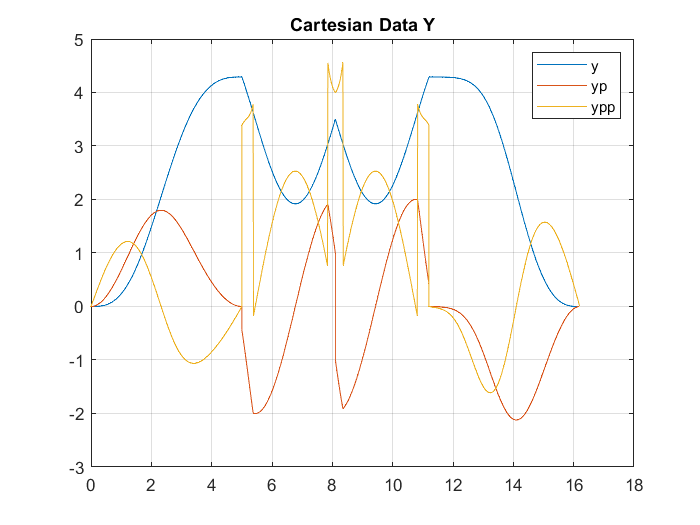

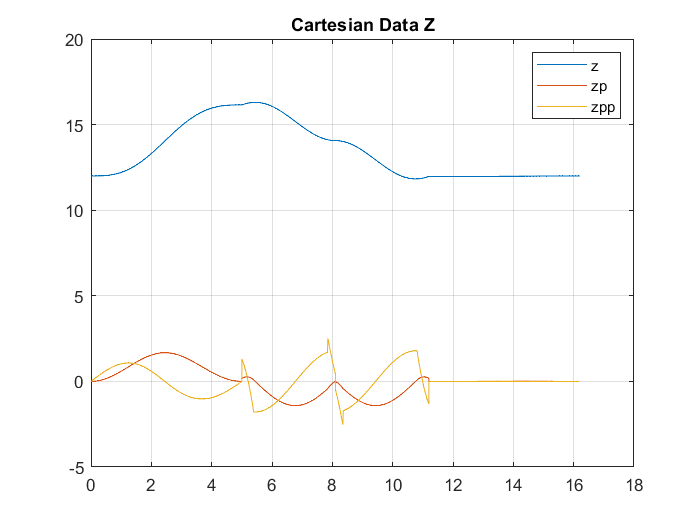

Plot_Graphs_Dir_Kinematics_noDebug_AAA(S_TOT,SP_TOT,SPP_TOT,TT_TOT)

- Plot Coppie:

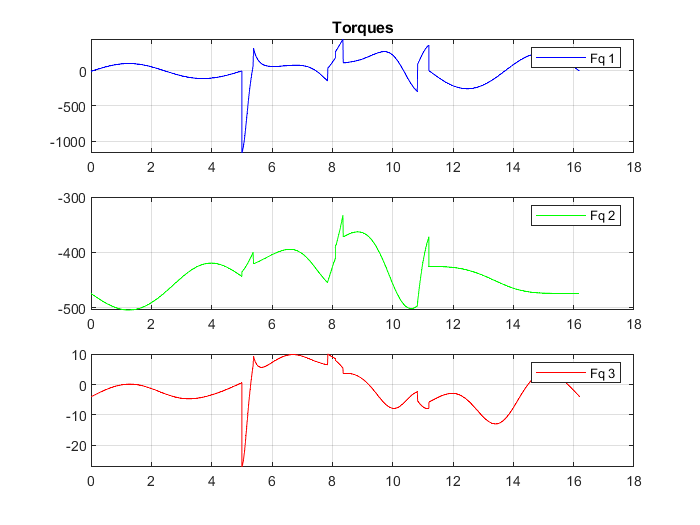

h = figure;
set(h,'name','torques')
subplot(3,1,1)
plot(TT_TOT,CC1_TOT,'b')
legend("Fq 1")
grid on
title("Torques")

subplot(3,1,2)
plot(TT_TOT,CC2_TOT,'g')
legend("Fq 2")
grid on

subplot(3,1,3)
plot(TT_TOT,CC3_TOT,'r')
legend("Fq 3")
grid on

- Plot Energia:

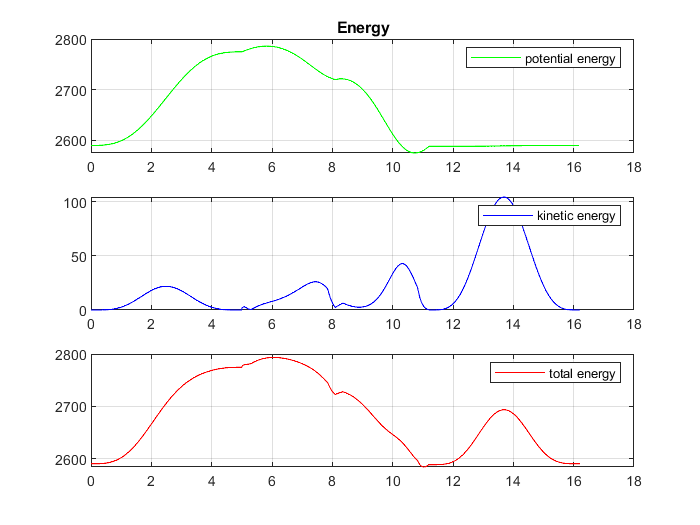

h = figure;
set(h,'name','energy') 

subplot(3,1,1)
plot(TT_TOT,EP_TOT,'g')
legend("potential energy")
grid on
title("Energy")

subplot(3,1,2)
plot(TT_TOT,EK_TOT,'b')
legend("kinetic energy")
grid on

subplot(3,1,3)
plot(TT_TOT,E_TOT,'r')
legend("total energy")
grid on

- Plot Potenze reali e teoriche:

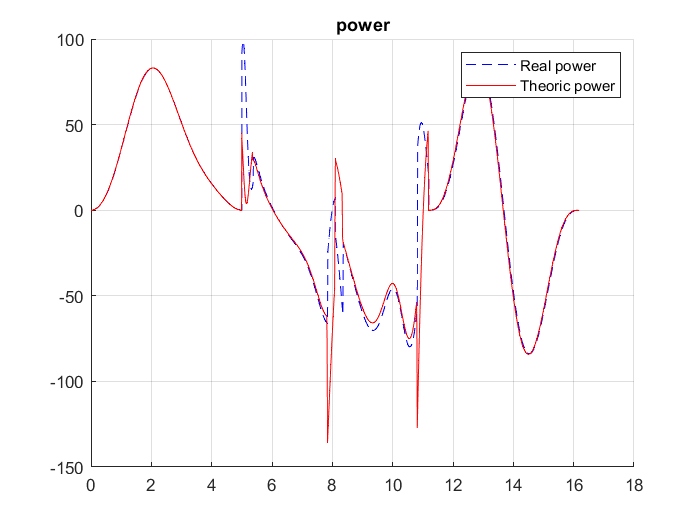

h = figure;
set(h,'name','power') 
hold on
grid on
plot(TT_TOT,WW_TOT,'b--')

plot(TT_TOT(1:length(P_TOT)),P_TOT,'r')
legend("Real power", "Theoric power")
title("power")